# SB01 and SB05 extraction 

SB01 and SB05 experienced a software glitch causing the data to be stored by appending files and not creating separate folders. This program extracts the data from the buoys (SB01 and SB05) that experienced this glitch. 

## Import Raw Data: Attempt 1 

%Specify directory of text file data 
projectdir = "C:\Users\uctsh\Documents\MATLAB\SHARC_BUOY_01_RAW_DATA\WD"; 
outdir = "C:\Users\uctsh\Documents\MATLAB\waveOutput";
outdir_2 = "C:\Users\uctsh\Documents\MATLAB";

%List wave data folders
folders = dir(projectdir);

%Sort List of folders 
folders = natsortfiles(folders);

%Text file dimensions for fread 
text_rows = 180000;
text_columns = 7; 

%concatenate text files into one file for each folder 
%Each file has 6x5 minute time series in seperate text files

concatFile = sprintf("WS%d.txt", 1);
actualfolderCount = 1; 

%Loop over every folder 
for folderCount = 1 : (8*19 + 1*11 + 1*5 + 11*3 + 1*1) % list of number of files

    if actualfolderCount == numel(folders) -2   
        actualfolderCount = 1;
    end
    
    concatFile = sprintf("WS%d.txt", folderCount);
    subfolder = sprintf("WS%d", actualfolderCount);
    outFileName = fullfile(outdir, concatFile); 
    outFile = fopen(outFileName, "w");
    
    subfoldername = fullfile(projectdir, subfolder);
    files = dir(subfoldername);
    files = natsortfiles(files);

    %concatenate files in subfolder
    for fileCount = 1 : length(files) - 2
        
        filename = fullfile(subfoldername, files(fileCount).name);
        
        if isfile(filename)    
            tempfile = fopen(filename, 'r');
            tempData = fread(tempfile, [text_rows, text_columns], 'uint8');
            fwrite(outFile, tempData, 'uint8');
            fclose(tempfile); 
        else 
            fprintf('File does not exist.\n'); 
        end
    
    end
    
    fclose("all");

    actualfolderCount = actualfolderCount+1;  

end

File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not

## Import Raw Data: Attempt 2

%Specify directory of text file data 
projectdir = "C:\Users\uctsh\Documents\MATLAB\SHARC_BUOY_01_RAW_DATA\WD"; 
outdir = "C:\Users\uctsh\Documents\MATLAB\waveOutput";
outdir_2 = "C:\Users\uctsh\Documents\MATLAB";

%List wave data folders
folders = dir(projectdir);

%Sort List of folders 
folders = natsortfiles(folders);

%Text file dimensions for fread 
text_rows = 30000;
text_columns = 7; 

%concatenate text files into one file for each folder 
%Each file has 6x5 minute time series in seperate text files

concatFile = sprintf("WS%d.txt", 1);
actualfolderCount = 1

actualfolderCount = 1

directoryLoop = 1; %counter to keep track of loops of the directory 

%Loop over every folder 
for folderCount = 1 : (8*19 + 1*11 + 1*5 + 11*3 + 1*1) % list of number of files

    if actualfolderCount == numel(folders) -2   
        actualfolderCount = 1;
        directoryLoop = directoryLoop + 1; 
    end
    
    concatFile = sprintf("WS%d.txt", folderCount);
    subfolder = sprintf("WS%d", actualfolderCount);
    outFileName = fullfile(outdir, concatFile); 
    outFile = fopen(outFileName, "w");
    
    subfoldername = fullfile(projectdir, subfolder);
    files = dir(subfoldername);
    files = natsortfiles(files);

    %concatenate files in subfolder
    for fileCount = 1 : length(files)
        
        filename = fullfile(subfoldername, files(fileCount).name);
        
        tempfile = fopen(filename, 'r');

        if isfile(filename)      

            for lineCount = 1:directoryLoop*text_rows
                tempData = fgets(tempfile); 
                if lineCount > (directoryLoop-1)*text_rows 
                    fwrite(outFile, tempData, 'uint8');
                end
            end

            fclose(tempfile); 
        else 
            fprintf('File does not exist.\n'); 
        end
    
    end
    
    fclose("all");

    actualfolderCount = actualfolderCount+1;  

end

File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not

## Create Text file with full dataset


outFileName = fullfile(outdir_2, "WS_All.txt"); 
outFile = fopen(outFileName, "w"); 

files = dir(outdir);
files = natsortfiles(files);

%Create concatenated text file with all data
for fileCount = 1 : length(files) 
        
        filename = fullfile(outdir, files(fileCount).name);
        
        if isfile(filename)    
            tempfile = fopen(filename, 'r');
            tempData = fread(tempfile, 'uint8');
            fwrite(outFile, tempData, 'uint8');
            fclose(tempfile); 
        else 
            fprintf('File does not exist.\n'); 
        end
    
end

File does not exist.
File does not exist.


    
fclose("all");

## Read Data into Table 

%Specify variables
opts = delimitedTextImportOptions("NumVariables", 7);
opts.VariableNames = ["TimeUTC","Surge", "Sway", "Heave", "Roll", "Pitch", "Yaw"];
opts.VariableTypes = ["datetime", "double", "double", "double", "double", "double", "double"];

%Read in table
wavefile = fullfile(outdir_2, "WS_All.txt");
WaveTable = readtable(wavefile, opts);



## Plot Raw Data for Analysis

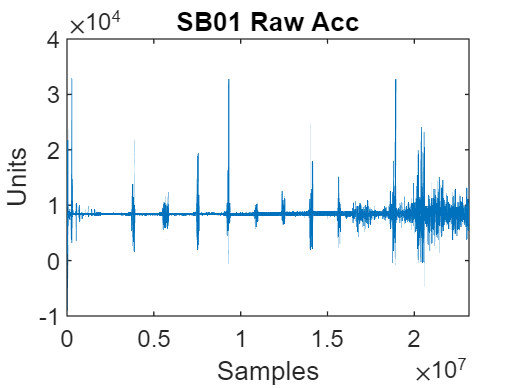

% Plot raw data 
plot(WaveTable.Heave);
title("SB01 Raw Acc");
xlabel('Samples');
ylabel('Units');

## Add dates to Table 

%Data has time but not date values, this code segment adds date values

%Covert Time values in table to datetime format 
WaveTable.TimeUTC = datetime(WaveTable.TimeUTC, 'Format','yyyy-MM-dd HH:mm:ss.SSS');

%calculate new day increment
newday = [true; diff(WaveTable.TimeUTC)<0];
daynum = cumsum(newday);

%Create array of days
date = datetime(2022, 07, 20) + caldays(daynum - 1); 
DateTimeUTC = date + timeofday(WaveTable.TimeUTC); 

%Add datetime 
WaveTable = addvars(WaveTable, DateTimeUTC, 'before', "TimeUTC"); 
WaveTable.TimeUTC = [];

%Specify Times after deployment 
WaveTable = WaveTable(WaveTable.DateTimeUTC > datetime(2022, 07, 20, 19, 10, 00), :);

## Differentiate Time Series on Table

%Add Count Label to differentiate between time series
newTimeSeries= [true; diff(WaveTable.TimeUTC)> minutes(5)];
timeSeriesCount = cumsum(newTimeSeries);
TimeSeriesNo = max(timeSeriesCount); 
WaveTable = addvars(WaveTable, timeSeriesCount, 'After', 'TimeUTC');
   